clear
load mnist_28.mat

% save mnist_28.mat

%selecting and saving images to train
numE = 400;
validP = 0.25;
idx1 = (training.labels == 1);
place1 = find(cumsum(idx1) > numE-1);
idx2 = (training.labels == 2);
place2 = find(cumsum(idx2) > numE-1);
idx4 = (training.labels == 4);
place4 = find(cumsum(idx4) > numE-1);
idx8 = (training.labels == 8);
place8 = find(cumsum(idx8) > numE-1);
images1 = training.images(:,:,idx1(1:place1));
images2 = training.images(:,:,idx2(1:place2));
images4 = training.images(:,:,idx4(1:place4));
images8 = training.images(:,:,idx8(1:place8));
trainingImages = cat(3, images1(:,:,1:(numE*(1-validP))), images2(:,:,1:numE*(1-validP)), images4(:,:,1:numE*(1-validP)), images8(:,:,1:numE*(1-validP)));
validationImages = cat(3, images1(:,:,(numE*(1-validP)+1):numE), images2(:,:,(numE*(1-validP)+1):numE), images4(:,:,(numE*(1-validP)+1):numE), images8(:,:,(numE*(1-validP)+1):numE));

trainingImagesNoised = trainingImages - randn(28)/7

trainingImagesNoised = trainingImagesNoised(:,:,1) =

   -0.0021   -0.0884    0.0981    0.1228    0.0693   -0.1781   -0.0079    0.0996   -0.1645    0.0404   -0.0453   -0.2815    0.1414    0.0240    0.2495    0.0967   -0.1014   -0.0278    0.1268   -0.1352   -0.0749    0.2364    0.0023    0.1552    0.1439   -0.0655   -0.0210    0.2210
   -0.0929    0.1687    0.2027   -0.0412    0.2004   -0.1391   -0.0286   -0.1163   -0.1127    0.2907    0.2121   -0.0384   -0.0929    0.1034   -0.0090    0.0103   -0.0021    0.0616   -0.0971    0.0751    0.1115    0.0391    0.1772    0.1212   -0.3449   -0.0127    0.1622   -0.1620
   -0.0150   -0.1298    0.0530    0.1769   -0.0835   -0.0532   -0.0050    0.1257    0.0788   -0.1110   -0.0093    0.0451   -0.0562    0.1482   -0.0535   -0.1589   -0.0494   -0.0003    0.1277    0.2261    0.0704    0.1827    0.0987   -0.1237   -0.0449    0.1346   -0.0170    0.1465
   -0.1801    0.0121    0.1602    0.1203   -0.0871    0.1191   -0.2020    0.1132   -0.0725   -0.2867   

delete('trainingImages2\*')
for k = 1:size(trainingImagesNoised, 3)
    imwrite(trainingImagesNoised(:,:,k),"trainingImages2\image"+num2str(k)+".png");
end

validationImagesNoised = validationImages - randn(28)/7

validationImagesNoised = validationImagesNoised(:,:,1) =

   -0.0224    0.1535    0.0806    0.2256   -0.0684    0.0020   -0.0222    0.1813   -0.1253   -0.0625    0.0313   -0.0926    0.1616    0.0590   -0.0414    0.0661    0.0546    0.0082    0.2179   -0.0486   -0.0562    0.1490   -0.0995    0.3335   -0.0818   -0.0938    0.0418   -0.0121
   -0.1149   -0.2094    0.2250   -0.0682   -0.0436   -0.0325   -0.1522    0.1052    0.2200    0.2905   -0.2728    0.1945    0.1637    0.0478   -0.0619    0.4264   -0.0656   -0.2074   -0.2966    0.0046    0.0279    0.1393   -0.0113    0.2903    0.1533    0.2102   -0.2317   -0.1231
   -0.2198    0.0319   -0.0072    0.1684    0.0471   -0.0617    0.1158   -0.0189    0.0423   -0.1749   -0.1043    0.1216    0.1386   -0.0976    0.0894    0.0888   -0.3930    0.0606    0.1508   -0.1705    0.0976   -0.0392    0.0622    0.0867    0.0436   -0.0147    0.0632    0.0698
   -0.1607    0.1120   -0.0166   -0.0751   -0.1888    0.1838   -0.0368   -0.1662    0.0974   -0.050

delete('validationImages2\*')
for k = 1:size(validationImagesNoised, 3)
imwrite(validationImagesNoised(:,:,k),"validationImages2\image"+num2str(k)+".png");
end

%creating imagedatastore from the files
imds = imageDatastore("trainingImages2\");
valds = imageDatastore("validationImages2\");

%creating a pixellabeldatastore
ldc = labelDefinitionCreator();
addLabel(ldc,'on',labelType.PixelLabel);
addLabel(ldc,'off',labelType.PixelLabel);
labelDefs = create(ldc);
clear pixelLabelImages
pixelIdx = trainingImages ~= 0;
pixelLabelImages(28,28,1:size(trainingImages, 3)) = 0;
pixelLabelImages(pixelIdx) = 1;
pixelLabelImages(~pixelIdx) = 2;
pixelLabelImages = uint8(pixelLabelImages);
clear dataFile;
dataFile(size(trainingImages, 3),1) = "a";

delete('pixelLabelImages2\*')
for k = 1:size(trainingImages, 3)
    imwrite(pixelLabelImages(:,:,k),"pixelLabelImages2\image"+num2str(k)+".png");
    dataFile(k,1) = pwd+"\pixelLabelImages2\image"+num2str(k)+".png";
end


labelData = table(dataFile,'VariableNames',{'PixelLabelData'});
gtDataSource = groundTruthDataSource(imds);

gTruth = groundTruth(gtDataSource,labelDefs,labelData);
pxds = pixelLabelDatastore(gTruth);
pximds = combine(imds,pxds);

%doing the same thing for validation set
clear pixelLabelValImages
pixelValIdx = validationImages ~= 0;
pixelLabelValImages(28,28,1:size(validationImages, 3)) = 0;
pixelLabelValImages(pixelValIdx) = 1;
pixelLabelValImages(~pixelValIdx) = 2;
pixelLabelValImages = uint8(pixelLabelValImages);
clear dataFileVal;
dataFileVal(size(validationImages, 3),1) = "a";

delete('pixelLabelValImages2\*')
for k = 1:size(validationImages, 3)
    imwrite(pixelLabelValImages(:,:,k),"pixelLabelValImages2\image"+num2str(k)+".png");
    dataFileVal(k,1) = pwd+"\pixelLabelValImages2\image"+num2str(k)+".png";
end

labelDataVal = table(dataFileVal,'VariableNames',{'PixelLabelData'});
gtDataSourceVal = groundTruthDataSource(valds);
gTruthVal = groundTruth(gtDataSourceVal,labelDefs,labelDataVal);
pxdsVal = pixelLabelDatastore(gTruthVal);
pximdsVal = combine(valds,pxdsVal);

%creating encoder decoder structure
encoderBlock = @(growthRate, inputDepth) [
    convolution2dLayer(3,inputDepth,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth+growthRate,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth+growthRate*2,"Padding",'same')
    batchNormalizationLayer
    reluLayer("Name","db"+num2str(inputDepth))];
decoderBlock = @(growthRate, inputDepth) [
    convolution2dLayer(3,inputDepth,"Padding",'same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,inputDepth-growthRate,"Padding",'same')
    batchNormalizationLayer
    reluLayer];

layers = [
    imageInputLayer([28 28 1])
    convolution2dLayer(3, 8, Padding="same")
    reluLayer
    encoderBlock(16,32)
    maxPooling2dLayer(2,"Stride",2)
    encoderBlock(32,64)
    maxPooling2dLayer(2,"Stride",2)
    convolution2dLayer(3, 128, Padding="same")
    reluLayer
    convolution2dLayer(3, 256, Padding="same")
    reluLayer
    transposedConv2dLayer(2,128,"Stride",2, "Name", "up1")
    depthConcatenationLayer(2)
    decoderBlock(64, 128)
    transposedConv2dLayer(2,64,"Stride",2, "Name","up2")
    depthConcatenationLayer(2)
    decoderBlock(32,64)
    convolution2dLayer(3, 16, Padding="same")
    reluLayer
    convolution2dLayer(3, 8, Padding="same")
    reluLayer
    convolution2dLayer(3, 2, Padding="same")
    softmaxLayer
    pixelClassificationLayer
];


%setting training options
options = trainingOptions( ...
'adam',...
'MiniBatchSize', 600,...
'MaxEpochs',3000, ...
'Plots', 'training-progress', ...
'ValidationData', pximdsVal, ...
'ValidationFrequency',20, ...
'ValidationPatience',10);

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:22 |       74.99% |       81.40% |       0.6227 |       0.4295 |          0.0010 |
|      10 |          20 |       00:24:09 |       85.51% |       84.02% |       0.2835 |       0.3002 |          0.0010 |
|      20 |          40 |       00:47:54 |       86.43% |       83.93% |       0.2720 |       0.3058 |          0.0010 |
|      25 |          50 |       00:59:44 |       86.64% |              |       0.2670 |              |          0.0010 |
|      3

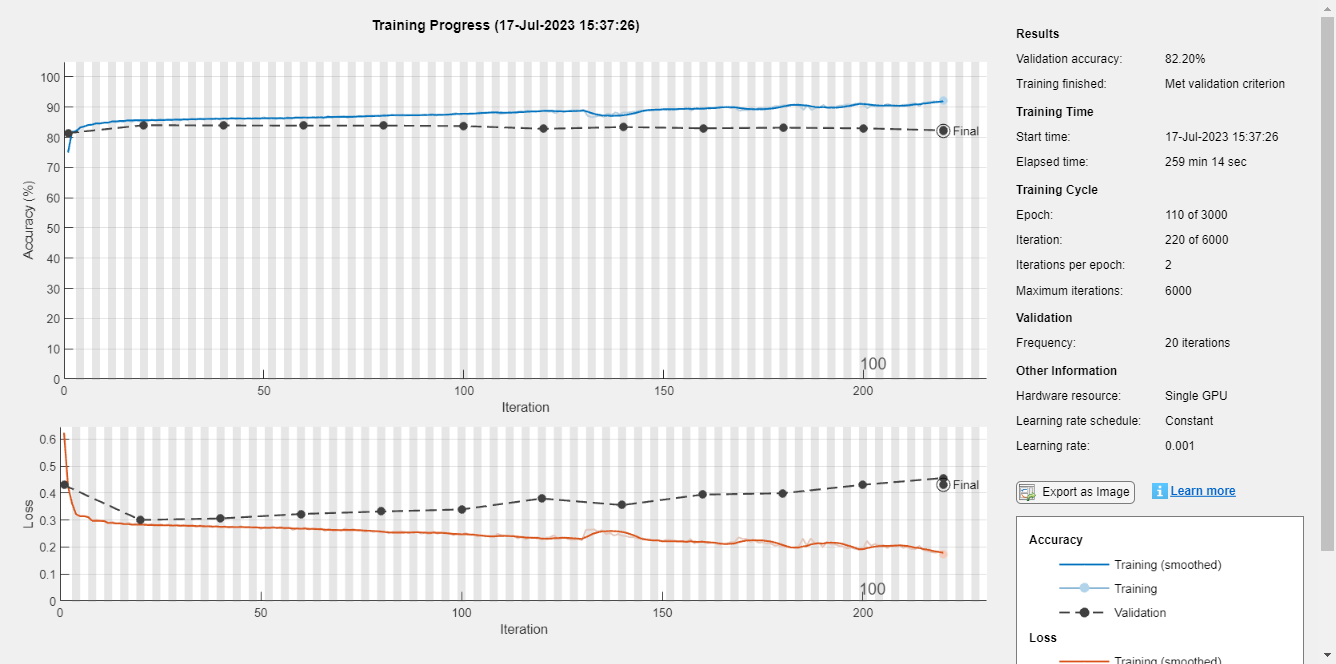

net =   DAGNetwork with properties:

         Layers: [51×1 nnet.cnn.layer.Layer]
    Connections: [52×2 table]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


%training net
net =  trainNetwork(pximds, lgraph_2, options)

save mnist_28.mat

% %test code
% for k=1:12
%     idx = 1;
%     trueCheck = 0;
%     while trueCheck ~= 1
%     idx = randi(size(test.images,3));
%     if test.labels(idx) == (4)
%         trueCheck = 1;
%     end  
%     end
%     subplot(2,12,k)
%     imshow(test.images(:,:,idx)*255)
%     title("ground "+num2str(idx))
%     subplot(2,12,k+12)
%     prediction = predict(net,test.images(:,:,idx)*255);
%     imshow(prediction(:,:,1))
%     title("prediction "+num2str(idx))
% end

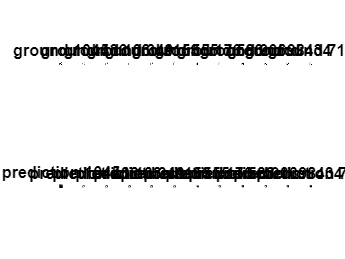

for k=1:12
    idx = randi(size(trainingImagesNoised,3));
    subplot(2,12,k)
    imshow(trainingImagesNoised(:,:,idx)*255)
    title("ground "+num2str(idx))
    subplot(2,12,k+12)
    prediction = predict(net,trainingImagesNoised(:,:,idx)*255);
    imshow(prediction(:,:,1))
    title("prediction "+num2str(idx))
end